# Read in the RX data

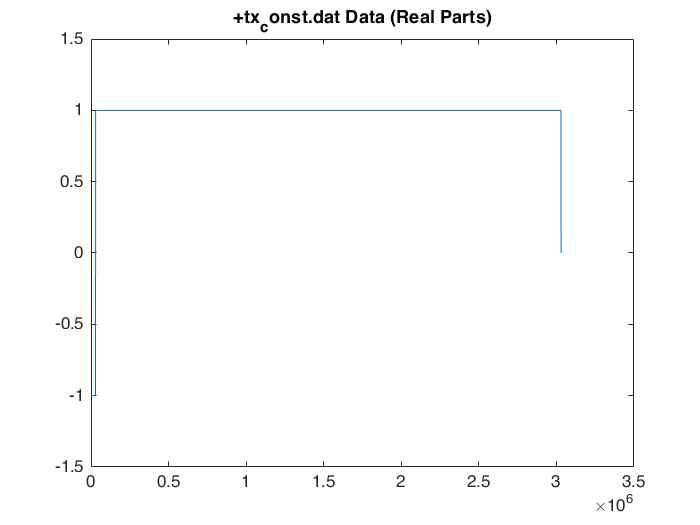

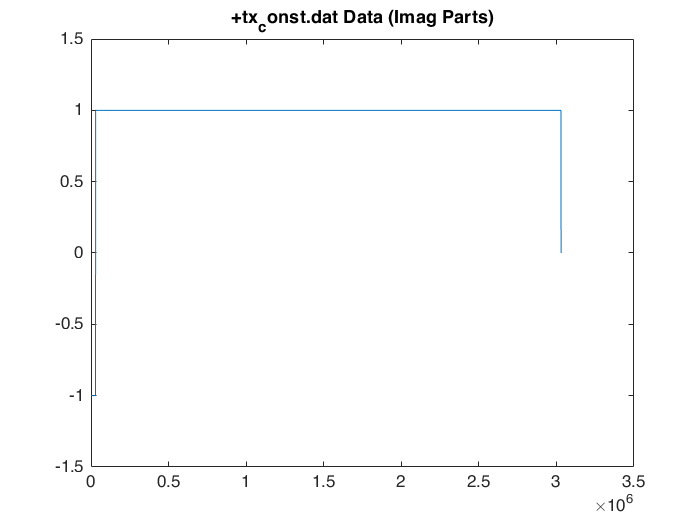

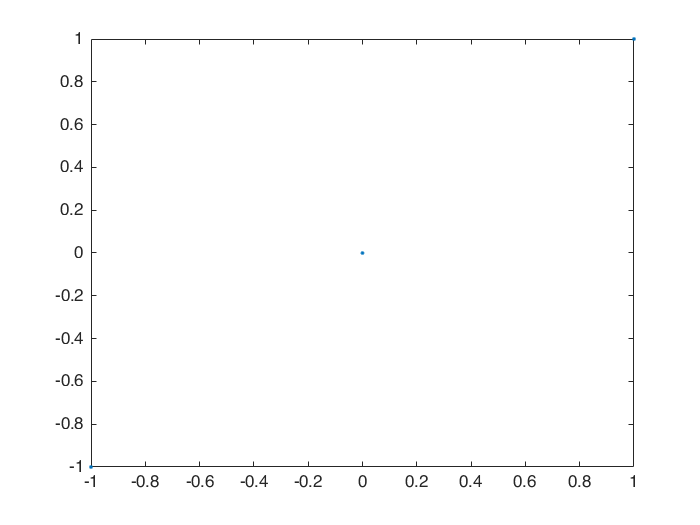

txname='+tx_const.dat'; % or enter '+tx_long.dat'
dat=read_and_plot(txname);

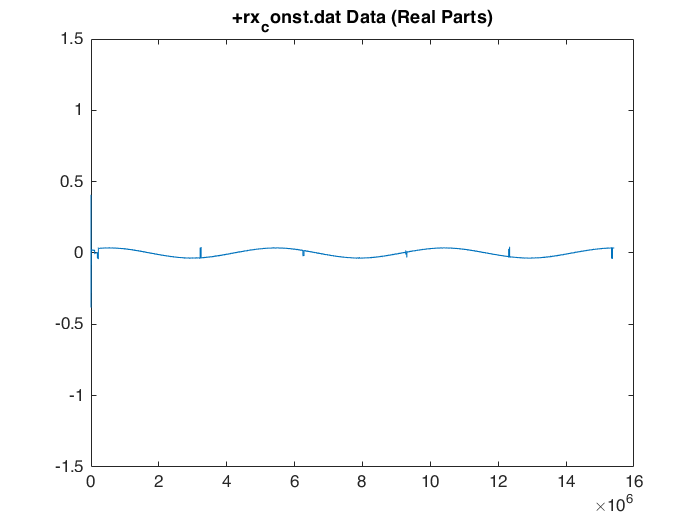

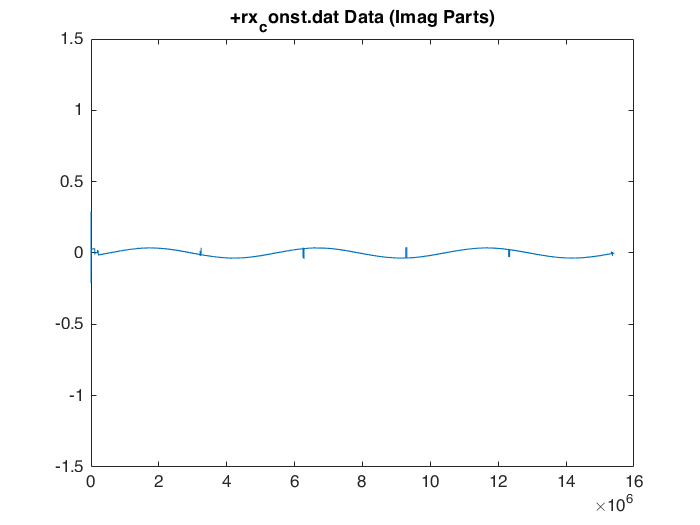

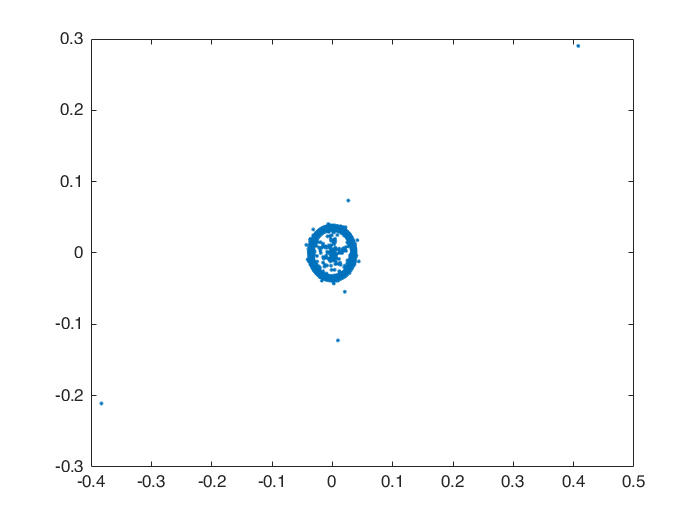

rxname='+rx_const.dat'; % or enter '+rx_long.dat'
read=read_and_plot(rxname);

## Cross-correlation of the real part

[r, lags]=xcorr(read,dat);
plot(lags,abs(r))
startPos = lags(find(abs(r) == max(abs(r))))

startPos = -361723

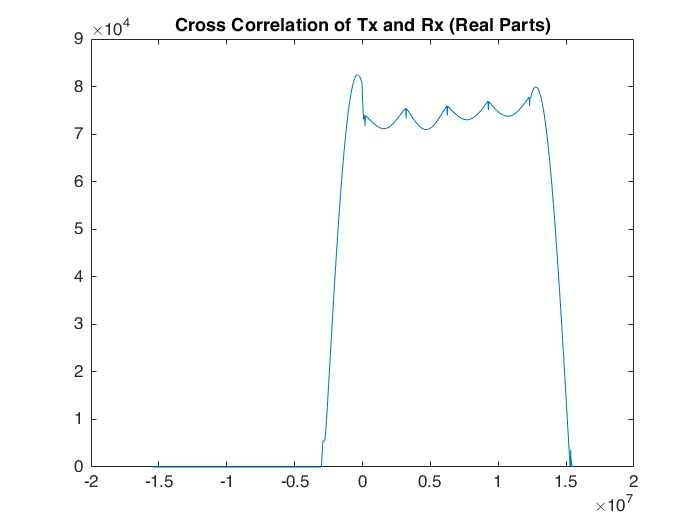

title('Cross Correlation of Tx and Rx (Real Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

% startPos=3555324; % random pulse;
startPos=3186173;

## Cross-correlation of the imaginery part

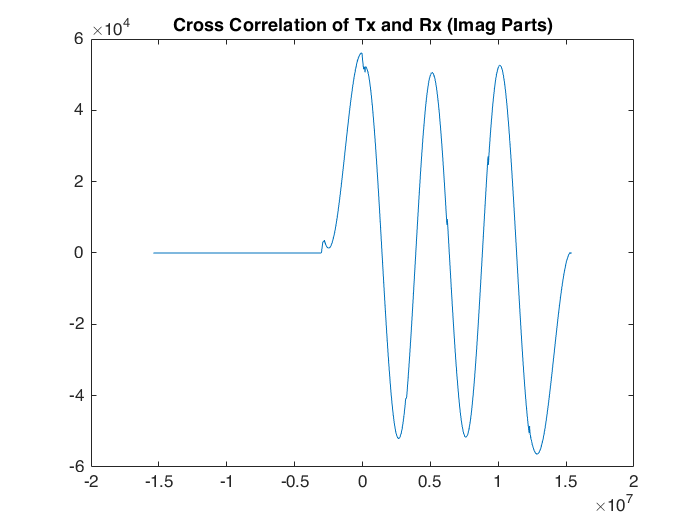

[r, lags]=xcorr(imag(read),imag(dat));
plot(lags,r)
title('Cross Correlation of Tx and Rx (Imag Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Attempt to adjust for phase shifting

power=6;
read_shifted=read(startPos:end);
% signal_rx = read_shifted(1:length(dat));
y_norm=read_shifted./rms(abs(read_shifted));
y_norm_4=y_norm.^power;

fft_y = fft(y_norm_4);
xval = max(abs(real(fft_y)))

xval = 6.0116e+06

yval = max(abs(imag(fft_y)))

yval = 8.2833e+06

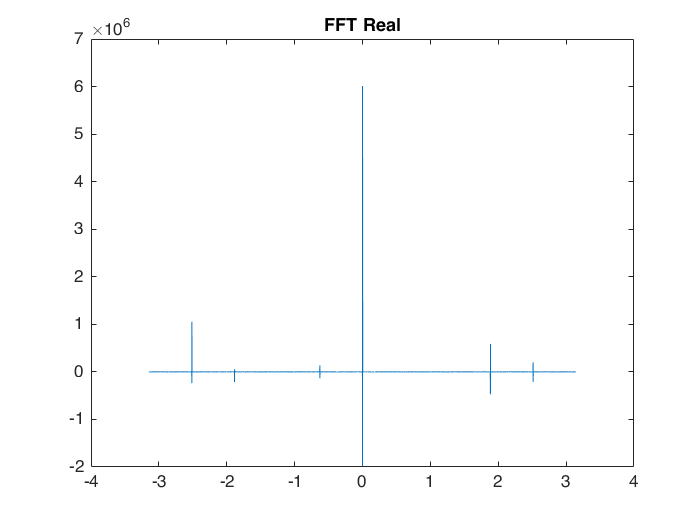

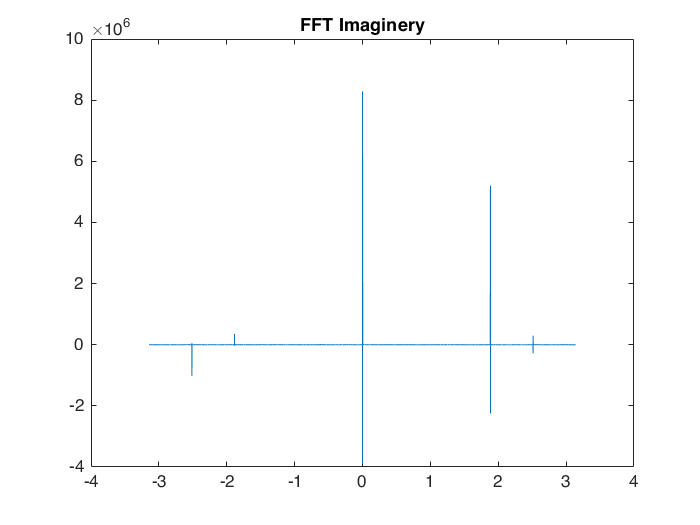

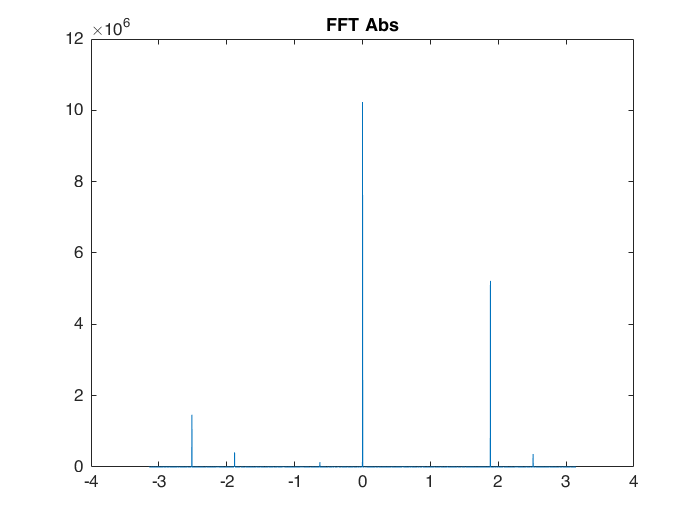

Fs=500000;
plot_FT(y_norm_4,Fs);

fft_y =  fftshift(fft(y_norm_4));
fft_x = 2*pi*1/Fs*linspace(-Fs/2, Fs/2*(length(y_norm)-1)/length(y_norm), length(y_norm));
real_max = real(fft_y(find(abs(real(fft_y)) == max(abs(real(fft_y))))));
im_max = imag(fft_y(find(abs(imag(fft_y)) == max(abs(imag(fft_y))))));
f_delta = fft_x(find(real(fft_y) == real_max))/power;
phi = (atan(im_max/real_max) - pi)/4

phi = -0.5497

k=1:length(read_shifted);
offset=exp(-1j*(f_delta*(k-1)*1+phi-pi/2));
%read_ds=read(153580:153580+length(dat)-1);
% read_ds=downsample(read_ds,20);
read_offset=times(read_shifted,offset.');

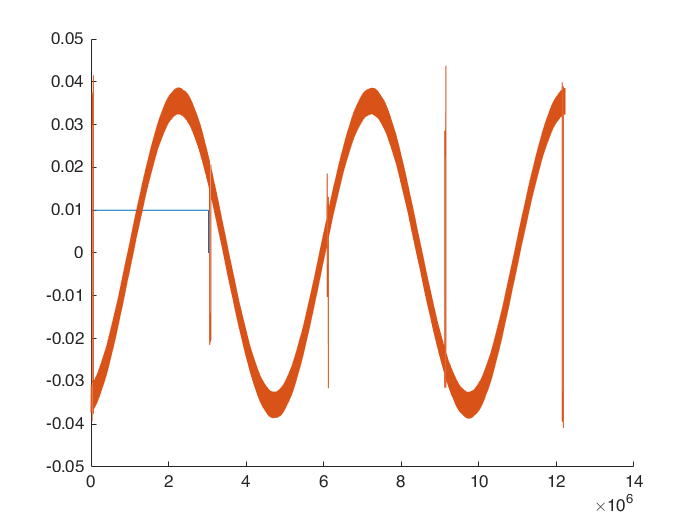

figure
hold on
plot(real(dat)*.01)
plot(real(read_shifted))
hold off

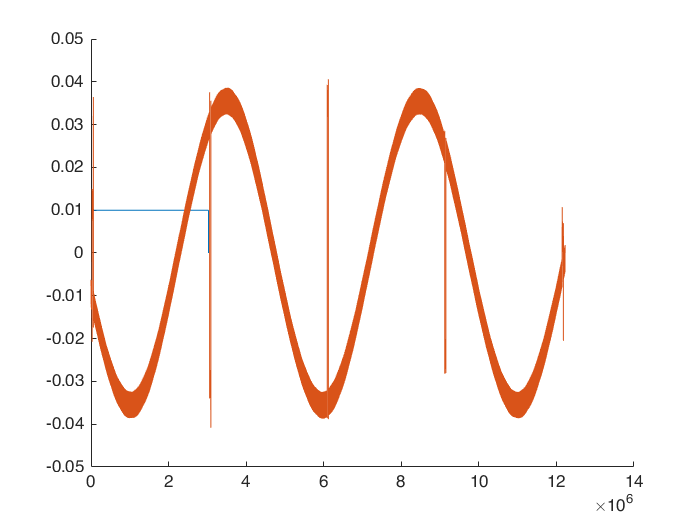

figure
hold on
plot(imag(dat)*.01)
plot(imag(read_shifted))
hold off

## Plot adjusted Results

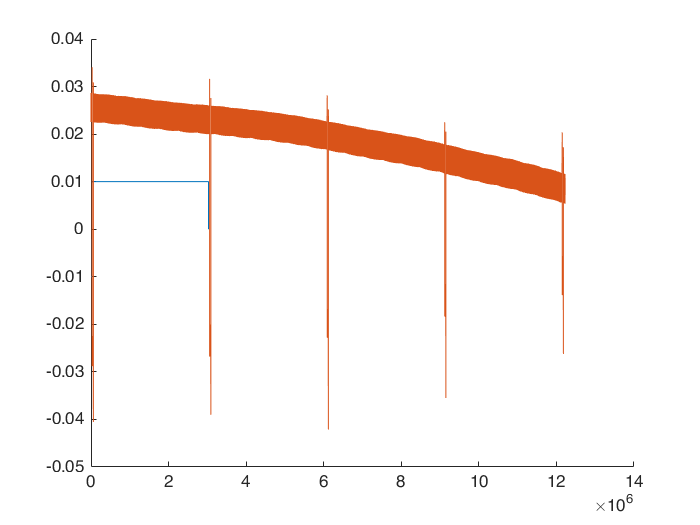

figure
hold on
plot(real(dat)*.01)
plot(real(read_offset))
hold off

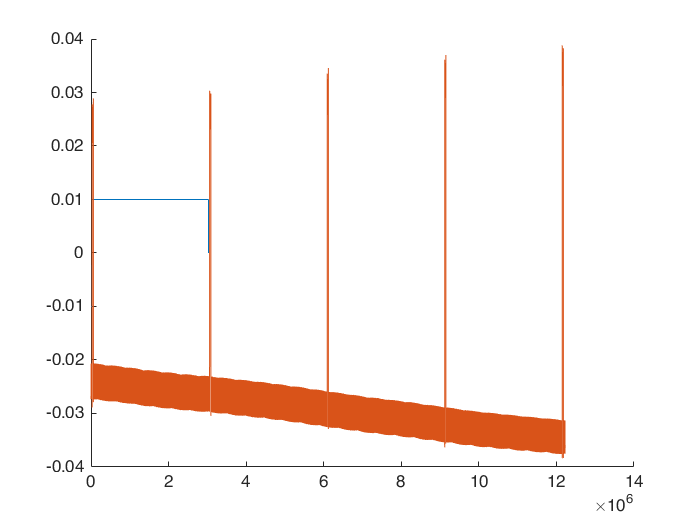

figure
hold on
plot(imag(dat)*.01)
plot(imag(read_offset))
hold off

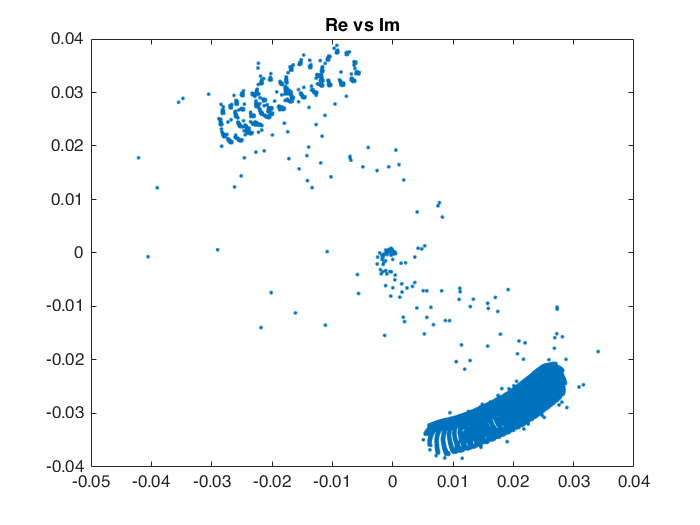

% Plot real vs imaginary
figure
plot(real(read_offset),imag(read_offset),'.')
title('Re vs Im')

% xlim([-1.25 1.25])
% ylim([-1.25 1.25])
data_ds=sign(downsample(dat,100,50));
offset_ds=sign(downsample(read_offset(1:length(dat)),100,50));
calc_error(data_ds,offset_ds)

ans = 0.5000